### **Задание 8**

Диапазон значений входов [-3; 3], 

Количество входов - 2, 

количество нейронов - 1, 

Входы персептрона: {[-1; 1] [-2; -1] [1; -2] [2; 0]}, 

Целевые выходы : {1 0 0 1}

inputs = [[-1; 1], [-2; -1], [1; -2], [2; 0]];
targets = [1, 0, 0, 1];

net = perceptron;
net = train(net, inputs, targets);
%view(net)

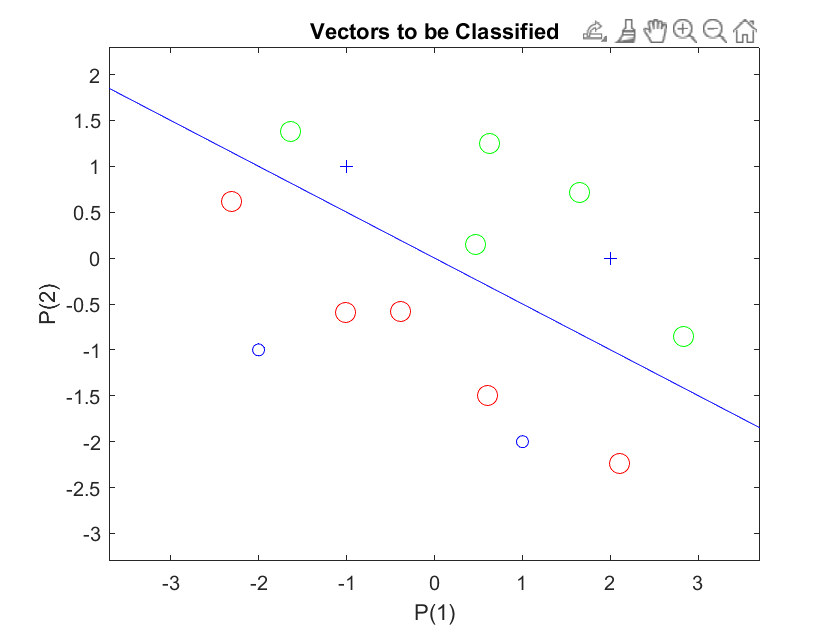

axis([-3 3 -3 3])
plotpv(inputs, targets)
plotpc(net.IW{1}, net.b{1})

hold on
for i=1:10
    point = ginput(1);
    if net(point') == 1
        scatter(point(1), point(2), 100,'green','o')
    else
        scatter(point(1), point(2), 100,'red','o')
    end
end

### Задание 11

Задайте три точки, определяющие разделяющую плоскость L. Создайте персептрон.

Рассчитайте смещение и вектор весов персептрона, перпендикулярный плоскости L. 

Задайте 10 случайных точек в рассматриваемом пространстве и визуализируйте работу персептрона.

figure;
A = [0 0 0];
B = [0 0 0];
C = [0 0 0];
AB = B - A;
AC = C - A;
normal = cross(AB, AC);

while ~all(normal) 
A = rand(1,3)*10;
B = rand(1,3)*10;
C = rand(1,3)*10;
AB = B - A;
AC = C - A;
normal = cross(AB, AC);

end
D = -dot(normal, A);

fprintf('Уравнение плоскости: %fx + %fy + %fz + %f = 0\n', normal(1), normal(2), normal(3), D);

Уравнение плоскости: -23.765995x + -6.614269y + -18.202886z + 276.653966 = 0


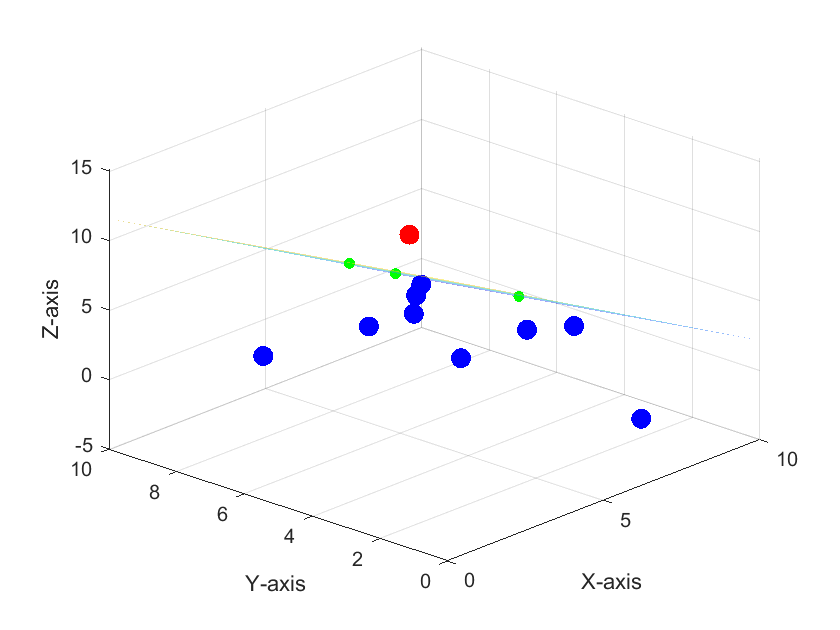


[x, y] = meshgrid(0:0.1:10);
z = (-normal(1) * x - normal(2) * y - D) / normal(3);

title(['Уравнение плоскости: %fx + %fy + %fz + %f = 0\n', normal(1), normal(2), normal(3), D]);
surf(x, y, z,'EdgeColor','none','FaceAlpha', 0.5)
hold on
P = [A;B;C];
scatter3(P(:,1), P(:,2), P(:,3), 30,'green','filled')
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

N = 100;
train_set = mvnrnd(5*ones(1, 3), 5*ones(1, 3), N);
labels = zeros(N, 1);

classify = @(x, y, z) sign([x y z] * normal' + D);
for i=1:N
    if classify(train_set(i,1), train_set(i,2), train_set(i,3)) >= 0
        labels(i) = 1;
    end
end

net = perceptron;
net = train(net, train_set', labels');
N = 10;
test = mvnrnd(5*ones(1, 3), 5*ones(1, 3), N);
labels = net(test');

hold on
for i=1:10
    if labels(i) == 1
        scatter3(test(i, 1), test(i, 2), test(i, 3), 100,'blue','o', 'filled')
    else
        scatter3(test(i, 1), test(i, 2), test(i, 3), 100,'red','o', 'filled')
    end
end

### Задание 12.

При помощи персептрона решить и визуализировать задачу распознавания заданного интерактивно (функция ginput):

б) выпуклого четырехугольника.

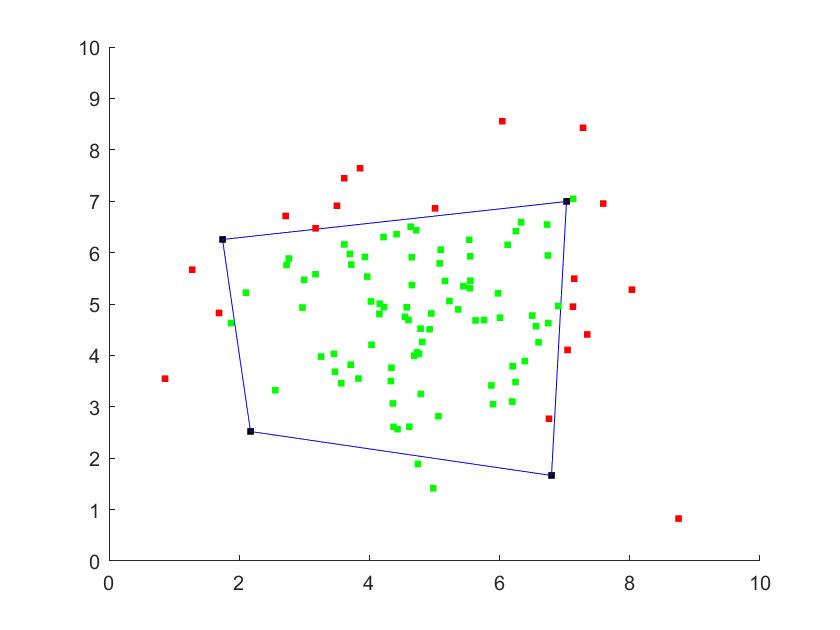

ans = 0.0175

clf
hold on
axis([0 10 0 10])

A = ginput(1);
scatter(A(1), A(2), 100,'black','.')
B = ginput(1);
scatter(B(1), B(2), 100,'black','.')
C = ginput(1);
scatter(C(1), C(2), 100,'black','.')
D = ginput(1);
scatter(D(1), D(2), 100,'black','.')

line([A(1) B(1)], [A(2) B(2)],'color','blue')
line([B(1) C(1)], [B(2) C(2)],'color','blue')
line([C(1) D(1)], [C(2) D(2)],'color','blue')
line([D(1) A(1)], [D(2) A(2)],'color','blue')

N = 200;
train_set = mvnrnd([5 5], [2 0; 0 2], N);
labels1 = zeros(N, 4);
labels2 = zeros(N, 1);

classify = @(x, y) sign([(A(1)-x)*(B(2)-y)-(B(1)-x)*(A(2)-y), (B(1)-x)*(C(2)-y)-(C(1)-x)*(B(2)-y), (C(1)-x)*(D(2)-y)-(D(1)-x)*(C(2)-y),  (D(1)-x)*(A(2)-y)-(A(1)-x)*(D(2)-y)]);
for i=1:200
    class = classify(train_set(i, 1), train_set(i, 2));
    class(class == -1) = 0;
    labels1(i,:) = class;
    if all(~labels1(i, :))
        labels2(i) = 1;
    else
        labels2(i) = 0;
    end
end

net1 = perceptron;
net1.trainParam.epochs=500;
net1 = train(net1, train_set', labels1');

net2 = perceptron;
net2.trainParam.epochs=500;
net2 = train(net2, labels1', labels2');

N = 100;
test = mvnrnd([5 5], [2 0; 0 2], N);
labels= net2(net1(test'));
for i=1:100
    if labels(i) == 1
        scatter(test(i, 1), test(i, 2), 100,'green','.')
    else
        scatter(test(i, 1), test(i, 2), 100,'red','.')
    end
end

### **Задание 13**

Решите при помощи однослойного двухнейронного персептрона задачу классификации.

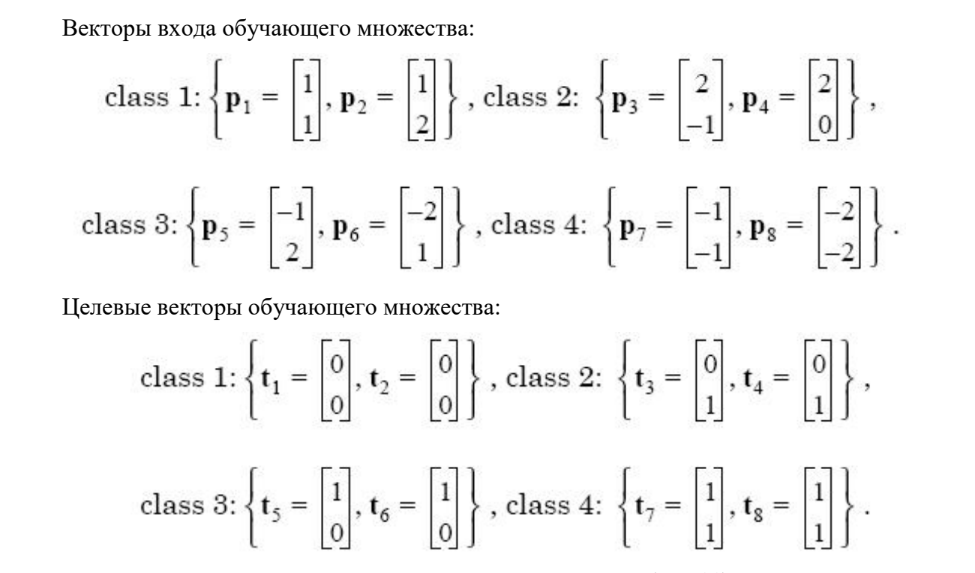

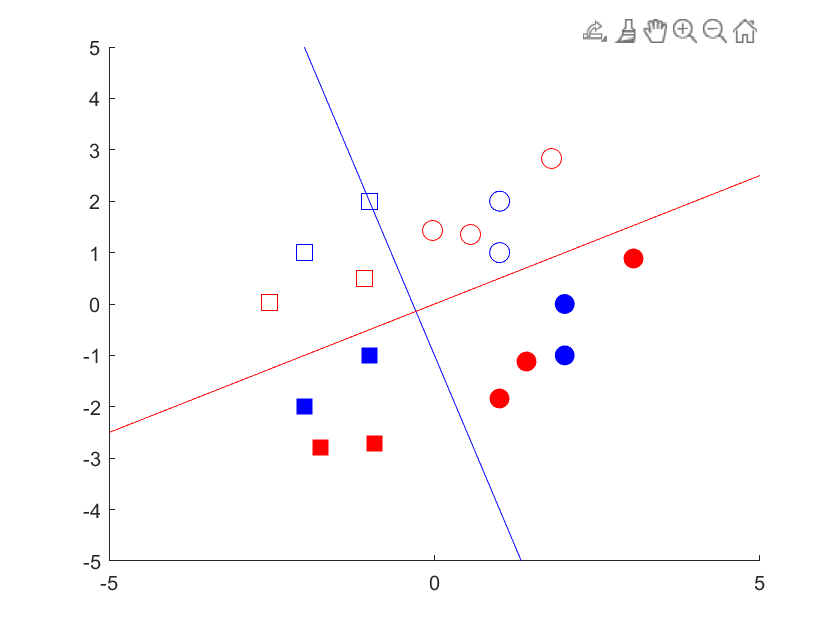

clf
hold on

P=[[1;1] [1;2] [2;-1] [2;0] [-1;2] [-2;1] [-1;-1] [-2;-2]];
T=[[0;0] [0;0] [0;1] [0;1] [1;0] [1;0] [1;1] [1;1]];

net = perceptron;
net = train(net, P, T);

hold on
axis([-5 5 -5 5])

class0 = P(:, [1 2]);
class1 = P(:, [3 4]);
class2 = P(:, [5 6]);
class3 = P(:, [7 8]);

scatter(class0(1, :), class0(2, :),100, 'bo'); 
hold on;
scatter(class1(1, :), class1(2, :), 100, 'bo', 'filled'); 
hold on;
scatter(class2(1, :), class2(2, :), 100, 'b', 'square'); 
hold on;
scatter(class3(1, :), class3(2, :), 100, 'b','square', 'filled');
hold off;

plotpc(net.IW{1}, net.b{1})

hold on
for n=1:10
    point = ginput(1);
    if net(point') == [0; 0]
        scatter(point(1), point(2),100,'r','o')
    end
    if net(point') == [0; 1]
        scatter(point(1), point(2),100,'r','o','filled')
    end
    if net(point') == [1; 0]
        scatter(point(1), point(2),100,'r','square')
    end
    if net(point') == [1; 1]
        scatter(point(1), point(2),100,'r','square', 'filled')
    end
end

### Задание 14

Создать, обучить и апробировать персептрон для принятия решения о зачислении в высшее учебное заведение абитуриентов, 

сдавших вступительные экзамены. Количество экзаменов задается (Preliminary Examination Number). 

Каждый экзамен оценивается по N-балльной шкале и имеет заданную нижнюю положительную границу (Lower Limit).

Зачислению подлежат абитуриенты, преодолевшие заданный суммарный порог (Total Threshold).

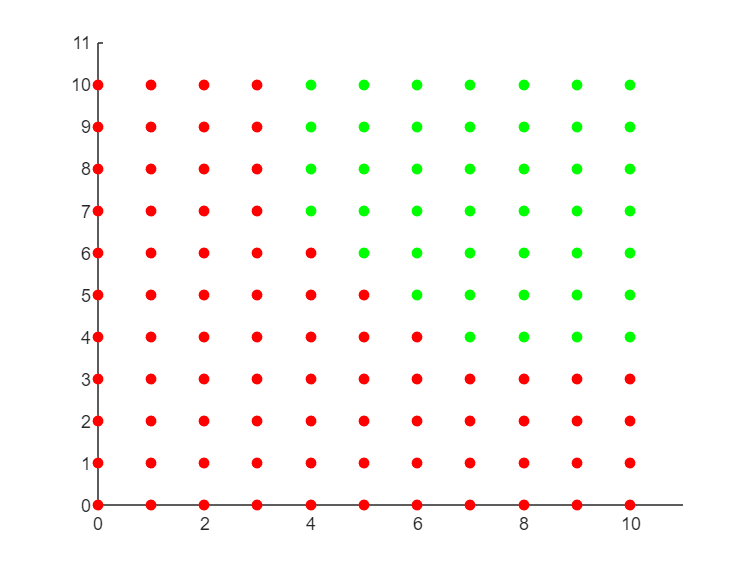

PreliminaryExaminationNumber = 2;
N = 10;
LowerLimit = 3;
TotalThreshold = 11;

numStudents = 100;
studs = randi([0, N], numStudents, PreliminaryExaminationNumber);
labels1 = zeros(numStudents, PreliminaryExaminationNumber + 1);
labels2 = zeros(numStudents, 1);

func = @(k) [sum(k) >= TotalThreshold, k > LowerLimit];
for i=1:numStudents
    labels1(i, :) = func(studs(i, :));
    if all(labels1(i, :)) 
        labels2(i) = 1;
    end
end

net1 = perceptron;
net1 = train(net1, studs', labels1');
net2 = perceptron;
net2 = train(net2, labels1', labels2');

NN = (N+1)^2 - 1;
values = zeros(NN, 2);

for i=0:NN
    values(i+1,1) = floor(i/(N+1));
    values(i+1,2) = mod(i, (N+1));
end
labels = net2(net1(values'));

clf
hold on
axis([0 N+1 0 N+1]);

for i=1:length(values)
    if labels(i) == 1
        scatter(values(i, 1), values(i, 2),'green','filled')
    else
        scatter(values(i, 1), values(i, 2),'red','filled')
    end
end